% 1. Cargar el archivo CSV

% Cambiar a la carpeta del archivo
cd 'C:\Users\beaga\Documents\TODO\TODO\industriales\tfg'

% Operar normalmente


% Opcional: Volver a la carpeta original

archivo = 'datos ciclo SOC-OCV (version 2).xlsx';
opts = detectImportOptions(archivo);
tabla = readtable(archivo, opts);


% 2. Extraer y renombrar variables (basado en las cabeceras del archivo)
tabla = tabla(9640:end, :);
voltaje = tabla.VOLTAJE/1000;
corriente=tabla.CORRIENTE;
tiempo_abs = tabla.Tiempo;

if ~isdatetime(tiempo_abs)
    tiempo_abs = datetime(tiempo_abs, 'InputFormat', 'yyyy-MM-dd HH:mm:ss:SSSSS');
end

% Tiempo relativo empezando en 0 segundos en el primer dato
tiempo = seconds(tiempo_abs - tiempo_abs(1));

% 3. Guardar en formato .mat
save('datos_procesados.mat', 'voltaje', 'corriente', 'tiempo');

% 1. Crear la tabla
T = table(voltaje, corriente, tiempo, 'VariableNames', {'Voltaje', 'Corriente', 'Tiempo'});

T.Carga=T.Corriente/3600;
T.CargaAcumulada = cumsum(T.Carga);

% 2. Guardar la tabla en un archivo .mat
save('datos_procesados_tabla.mat', 'T');

%carga acumulada negativa=159.0252
%carga acumulada positiva=159.252+5.4311
% Tabla 1: Desde el principio hasta la fila 114286
T1 = T(1:114300, :);
T1.Tiempo = T1.Tiempo - T1.Tiempo(1);           % ← Tiempo empieza en 0s

% === ELIMINAR REPOSO INICIAL DE LA DESCARGA ===
% Las primeras filas de T1 son un reposo (corriente ≈ 0) previo al
% inicio real de la descarga. En ese tramo el SOC se mantiene en ~1
% mientras el voltaje ya varía, lo que produce la subida vertical en
% SOC=1 al pintar la curva. Se recorta T1 para que empiece en la
% primera muestra con corriente de descarga real.
idx_inicio_descarga = find(abs(T1.Corriente) > 1e-3, 1, 'first');
if ~isempty(idx_inicio_descarga) && idx_inicio_descarga > 1
    fprintf('Se han eliminado %d muestras de reposo inicial en la descarga.', idx_inicio_descarga - 1);
    T1 = T1(idx_inicio_descarga:end, :);
    T1.Tiempo = T1.Tiempo - T1.Tiempo(1);       % ← Tiempo vuelve a empezar en 0s
end

% === NUEVO RECORTE: Hasta la primera vez que Voltaje <= 3.0 V ===
fila_final_T1 = find(T1.Voltaje == 3.0003, 1, 'first');   % Primera fila donde llega a 3V

if ~isempty(fila_final_T1)
    T1 = T1(1000:fila_final_T1, :);                       % ← Desde fila 1 hasta esa fila
    fprintf('✅ T1 recortada correctamente: desde fila 1 hasta fila %d (Voltaje = %.4f V)\n', ...
            fila_final_T1, T1.Voltaje(end));
else
    warning('No se encontró Voltaje <= 3.0 V en T1');
end  


T1.Carga = T1.Corriente / 3600;                 % Carga en Ah (por si no estaba)
T1.CargaAcumulada = cumsum(T1.Carga) - T1.Carga(1);
T1.CargaIntegrada = cumtrapz(T1.Tiempo, T1.Corriente) / 3600;

ultimo_valor_T1 = T1.CargaAcumulada(end);

% Tabla 2: Desde la fila 114287 hasta el final
T2 = T(114287:end, :);
T2.Tiempo = T2.Tiempo - T2.Tiempo(1);           % ← Tiempo empieza en 0s (¡esto era el problema!)


fila_final_T2 = find(T2.Voltaje >= 4.2, 1, 'first');    % Primera vez que llega a 4.2V

if ~isempty(fila_final_T2)
    T2 = T2(1:fila_final_T2, :);                         % Desde fila 1 de T2 hasta esa fila
    fprintf('✅ T2: desde fila 1 hasta fila %d (Voltaje = %.4f V)\n', ...
            fila_final_T2, T2.Voltaje(end));
end

✅ T2: desde fila 1 hasta fila 120191 (Voltaje = 4.2000 V)




T2.Carga = T2.Corriente / 3600;
T2.CargaAcumulada = cumsum(T2.Carga) - T2.Carga(1);
T2.CargaIntegrada = cumtrapz(T2.Tiempo, T2.Corriente) / 3600;

ultimo_valor_T2 = T2.CargaAcumulada(end);
CargaIntegrada2 = trapz(T2.Tiempo, T2.Corriente);   % en Coulomb (A·s)


T1.Soc=(-ultimo_valor_T1+T1.CargaAcumulada)/(-ultimo_valor_T1);
T2.Soc=T2.CargaAcumulada/(ultimo_valor_T2);


T1.SocIntegrado=(-ultimo_valor_T1+T1.CargaIntegrada)/(-ultimo_valor_T1);
T2.SocIntegrado=T2.CargaIntegrada/(ultimo_valor_T2);

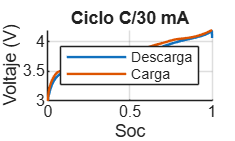

figure('Color', 'w');
hold on; % Permitir varias gráficas sobrepuestas



plot(T1.SocIntegrado, T1.Voltaje, 'LineWidth', 1.2, 'DisplayName', 'Descarga');
plot(T2.SocIntegrado, T2.Voltaje, 'LineWidth', 1.2, 'DisplayName', 'Carga');

xlabel('Soc');
ylabel('Voltaje (V)');
title('Ciclo C/30 mA');
legend('Location', 'best'); % Muestra la leyenda en el mejor hueco libre
grid on;
hold off;

% 1. Definir los puntos de SoC cada 0.05
soc_grid = (0:0.05:1)';

% 2. Limpiar datos por si acaso y ordenar para interpolar bien
[T1_soc_unique, idx1] = unique(T1.SocIntegrado);
T1_volt_unique = T1.Voltaje(idx1);

[T2_soc_unique, idx2] = unique(T2.SocIntegrado);
T2_volt_unique = T2.Voltaje(idx2);

% 3. Interpolar voltaje para cada SoC de la rejilla
OCV_T1 = interp1(T1_soc_unique, T1_volt_unique, soc_grid, 'linear', 'extrap');
OCV_T2 = interp1(T2_soc_unique, T2_volt_unique, soc_grid, 'linear', 'extrap');

% 4. Mostrar por pantalla
tabla_T1 = table(soc_grid, OCV_T1, 'VariableNames', {'SoC', 'Voltaje_T1'});
tabla_T2 = table(soc_grid, OCV_T2, 'VariableNames', {'SoC', 'Voltaje_T2'});

disp('Valores de voltaje para cada SoC (T1 - Descarga):')

Valores de voltaje para cada SoC (T1 - Descarga):


disp(tabla_T1)

    SoC     Voltaje_T1
    ____    __________

       0      3.0027  
    0.05       3.393  
     0.1       3.478  
    0.15      3.5104  
     0.2      3.5483  
    0.25      3.5806  
     0.3      3.6116  
    0.35      3.6438  
     0.4      3.6768  
    0.45      3.7135  
     0.5      3.7518  
    0.55      3.7877  
     0.6      3.8227  
    0.65      3.8622  
     0.7      3.9214  
    0.75      3.9672  
     0.8      4.0074  
    0.85      4.0411  
     0.9       4.073  
    0.95      4.1142  
       1      4.0639  




disp('Valores de voltaje para cada SoC (T2 - Carga):')

Valores de voltaje para cada SoC (T2 - Carga):


disp(tabla_T2)

    SoC     Voltaje_T2
    ____    __________

       0      3.0025  
    0.05      3.4635  
     0.1       3.521  
    0.15      3.5618  
     0.2      3.6058  
    0.25      3.6426  
     0.3      3.6725  
    0.35      3.7049  
     0.4      3.7486  
    0.45      3.7995  
     0.5      3.8418  
    0.55      3.8738  
     0.6      3.9044  
    0.65      3.9448  
     0.7      3.9813  
    0.75      4.0222  
     0.8      4.0498  
    0.85      4.0658  
     0.9      4.0919  
    0.95      4.1359  
       1         4.2  

